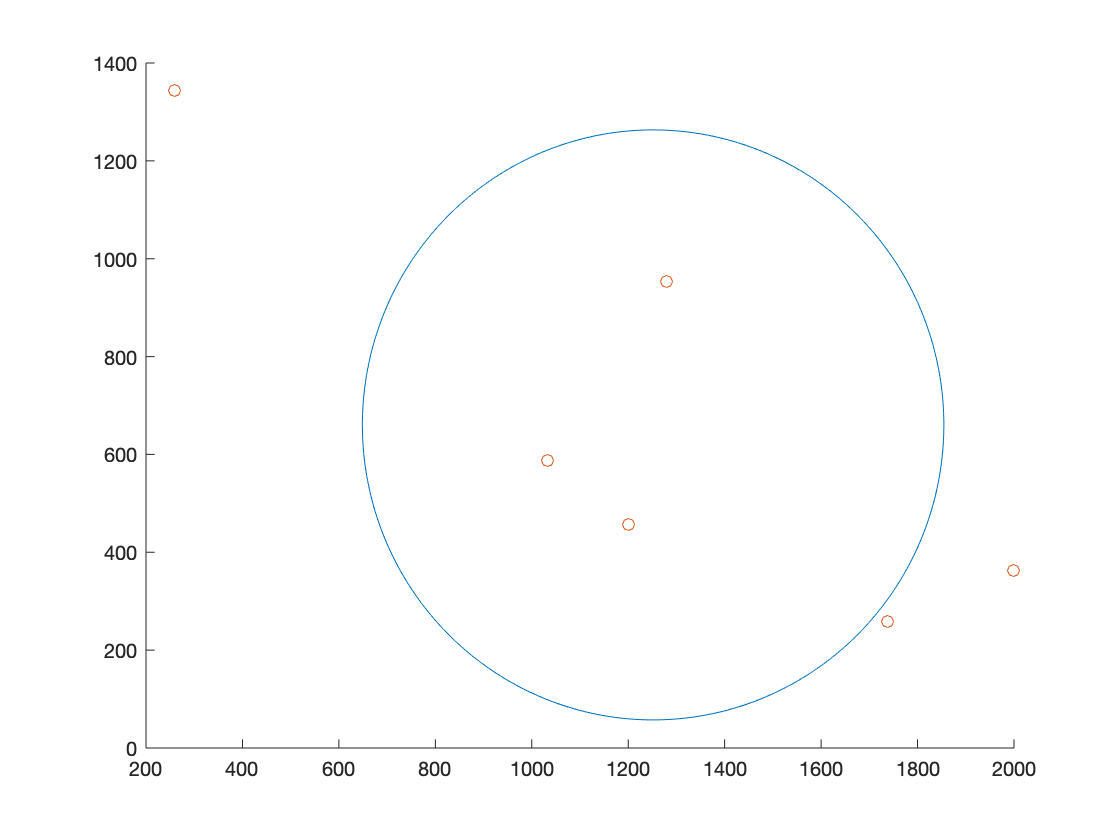

clear, clc;
K = 6;
W = 2000*rand(K,2);
d_min = 100;
T = 210;
H = 100;
NoisePower = 10^(-14);
d0 = 1;
Rho0 = 10^(-6);
Pmax = 0.1;
Vmax = 50;
epsilon = 10^-2;
d_min = 100;
M = 1;
%N = Vmax*T/(H*epsilon);
N = 450;
Tau = 100;
N2 = N*Tau;
%Slot_assignment = Tau * A
deltaT = T/N;
Max_Dist = deltaT * Vmax;
%%
GeometricCenter = sum(W)/K;
Radius = max(vecnorm(W - GeometricCenter,2,2));
RadiusMax = Vmax * T / (2*pi);

filepath = 'packings/cci' + string(M) + '.txt';
Radii = load('radius.txt');
Radius_cp = Radii(M,2)*Radius/2;
cp_coords = load(filepath);
cp_coords = cp_coords(:, 2:3)*Radius;
R_traj = min(RadiusMax, Radius_cp);

Theta = linspace(0, 2*pi, N);
Small_Trajectory_Coords = GeometricCenter + cp_coords;
Xs = Small_Trajectory_Coords(:,1) + R_traj*cos(Theta);
Xs = reshape(Xs, [M, 1, N]);
Ys = Small_Trajectory_Coords(:,2) + R_traj*sin(Theta);
Ys = reshape(Ys, [M, 1, N]);
Trajectory_guess = [Xs, Ys];
%Q_guess = 
%plot(Xs(1,:), Ys(1,:), Xs(2,:), Ys(2,:));

for i = 1:M
    hold on
    plot(Xs(i,:), Ys(i,:));
end
scatter(W(:,1), W(:,2))

%%
P_init = ones(M, N)*Pmax;
%A_init = repmat([0.99*ones(K,1) zeros(K,M-1)], [1,1,N]);
A_init = rand(K,M);
A_init = .99 * A_init / sum(A_init, 'all');
A_init = repmat(A_init, [1,1,N]);
Q_init = Trajectory_guess;
%%
[obj, ~, ~] = UserScheduling(A_init, P_init, Trajectory_guess, K, M, N, Rho0, H, W, NoisePower);
%% Defining Optimization Setup
%A = zeros(K, M, N);
A = optimvar('A', K,M,N, 'Type', 'continuous', 'LowerBound', 0, "UpperBound", 1);
%Q = zeros(M, 2, N);
Q = optimvar('Q', M,2,N, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', 2000);
%P = zeros(M,N);
P = optimvar('P', M,N, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', Pmax);



for i = 1:15
    [f, A_sum_k, A_sum_m] = fcn2optimexpr(@UserScheduling, A, P_init, Q_init, K, M, N, Rho0, H, W, NoisePower);
    problem = optimproblem('ObjectiveSense', 'max');
    problem.Objective = f;
    
    problem.Constraints.cons1 = A_sum_k <= 1;
    problem.Constraints.cons2 = A_sum_m <= 1;
    
    %show(problem);
    
    x0.A = A_init;
    
    options = optimoptions('fmincon', 'Display', 'iter', 'MaxFunctionEvaluations', 100000, 'OptimalityTolerance', 1.0000e-04);
    [sol, fval, exitflag, output] = solve(problem, x0, 'Options', options)
    %obj = fcn2optimexpr
    %problem.Objective = SINR
    %%
    A_init = sol.A;
    
    [f2, speed_constraint, initial_final, inter_uav_distance] = fcn2optimexpr(@TrajectoryOptimization,A_init, P_init, Q, K, M, N, Rho0, H, W, NoisePower, d_min);
    
    problem2 = optimproblem('ObjectiveSense', 'max');
    problem2.Objective = f2;
    
    options = optimoptions('fmincon', 'Display', 'iter', 'MaxFunctionEvaluations', 100000, 'OptimalityTolerance', 1.0000e-06);
    
    deltaT = T/N;
    Max_Dist = deltaT * Vmax
    
    problem2.Constraints.speed = speed_constraint <= Max_Dist;
    problem2.Constraints.repeat = initial_final <= 1.0000e-10;
    
    x1.Q = Q_init;
    
    [sol2, fval2, exitflag2, output2] = solve(problem2, x1, 'Options', options);
    Q_init = sol2.Q;
end


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0    2701   -7.459838e-01    0.000e+00    1.345e-03
    1    5402   -6.930619e-01    0.000e+00    1.345e-03    6.981e-01
    2    8103   -6.856636e-01    0.000e+00    1.345e-03    3.184e-01
    3   10804   -6.386153e-01    0.000e+00    1.345e-03    1.384e+00
    4   13505   -6.074385e-01    0.000e+00    1.345e-03    1.360e+00
    5   16206   -5.964201e-01    0.000e+00    1.345e-03    1.152e+00
    6   18907   -6.087104e-01    0.000e+00    1.345e-03    4.148e-01
    7   21608   -6.176763e-01    0.000e+00    1.345e-03    1.930e-01
    8   24309   -6.208826e-01    0.000e+00    1.345e-03    1.713e-01
    9   27010   -6.222132e-01    0.000e+00    1.000e-03    3.380e-01
   10   29711   -6.415630e-01    0.000e+00    1.057e-03    2.872e-01
   11   32412   -6.914036e-01    0.000e+00    1.251e-03    9.089e-01
   12   35113  

sol = struct with fields:
    A: [6×1×450 double]


fval = 0.8700

exitflag =     SolverLimitExceeded


output = struct with fields:
         iterations: 37
          funcCount: 102638
    constrviolation: 0
           stepsize: 1.6606
          algorithm: 'interior-point'
      firstorderopt: 3.9811e-04
       cgiterations: 0
            message: '↵Solver stopped prematurely.↵↵fmincon stopped because it exceeded the function evaluation limit,↵options.MaxFunctionEvaluations = 1.000000e+05.↵↵'
             solver: 'fmincon'


Max_Dist = 23.3333


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     901   -8.699972e-01    0.000e+00    3.924e-06
    1    1802   -8.699972e-01    0.000e+00    3.924e-06    7.322e-02
    2    2703   -8.699972e-01    0.000e+00    3.924e-06    2.245e-02
    3    3605   -8.699972e-01    0.000e+00    3.924e-06    2.301e-01
    4    4507   -8.699973e-01    0.000e+00    3.924e-06    1.665e-01
    5    5408   -8.699973e-01    0.000e+00    3.924e-06    1.796e-01
    6    6309   -8.699975e-01    0.000e+00    3.924e-06    7.559e-01
    7    7210   -8.699977e-01    0.000e+00    3.924e-06    1.088e+00
    8    8111   -8.699983e-01    0.000e+00    3.924e-06    3.025e+00
    9    9012   -8.699990e-01    0.000e+00    3.924e-06    3.771e+00
   10    9913   -8.699995e-01    0.000e+00    3.924e-06    2.824e+00
   11   10814   -8.699995e-01    0.000e+00    3.924e-06    1.379e-01
   12   11715  


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0    2701   -9.051440e-01    0.000e+00    4.877e-04
    1    5402   -8.545872e-01    0.000e+00    4.877e-04    6.002e-01
    2    8103   -8.443509e-01    0.000e+00    4.877e-04    2.555e-01
    3   10804   -7.754234e-01    0.000e+00    4.877e-04    1.446e+00
    4   13505   -7.014943e-01    0.000e+00    4.877e-04    1.872e+00
    5   16206   -6.467756e-01    0.000e+00    4.917e-04    1.771e+00
    6   18907   -6.478053e-01    0.000e+00    5.284e-04    5.726e-01
    7   21608   -6.510503e-01    0.000e+00    5.499e-04    3.683e-01
    8   24309   -6.517034e-01    0.000e+00    5.588e-04    2.649e-01
    9   27010   -6.461162e-01    0.000e+00    5.659e-04    3.502e-01
   10   29711   -6.418666e-01    0.000e+00    5.689e-04    3.300e-01
   11   32412   -6.411370e-01    0.000e+00    5.681e-04    1.374e-01
   12   35113  

sol = struct with fields:
    A: [6×1×450 double]


fval = 0.9594

exitflag =     SolverLimitExceeded


output = struct with fields:
         iterations: 37
          funcCount: 102638
    constrviolation: 0
           stepsize: 0.2435
          algorithm: 'interior-point'
      firstorderopt: 4.3501e-04
       cgiterations: 0
            message: '↵Solver stopped prematurely.↵↵fmincon stopped because it exceeded the function evaluation limit,↵options.MaxFunctionEvaluations = 1.000000e+05.↵↵'
             solver: 'fmincon'


Max_Dist = 23.3333


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     901   -9.594037e-01    1.127e-01    4.200e-06
    1    1802   -9.594041e-01    0.000e+00    4.200e-06    1.480e+00
    2    2703   -9.594041e-01    0.000e+00    4.200e-06    8.107e-01
    3    3604   -9.594047e-01    0.000e+00    4.200e-06    1.441e+00
    4    4505   -9.594054e-01    0.000e+00    4.200e-06    1.910e+00
    5    5406   -9.594074e-01    0.000e+00    4.200e-06    4.371e+00
    6    6307   -9.594107e-01    0.000e+00    4.200e-06    6.596e+00
    7    7208   -9.594135e-01    0.000e+00    4.200e-06    4.983e+00
    8    8109   -9.594159e-01    0.000e+00    4.200e-06    2.740e+00
    9    9011   -9.594216e-01    0.000e+00    4.201e-06    6.468e+00
   10    9912   -9.594229e-01    0.000e+00    4.201e-06    1.192e+00
   11   10813   -9.594230e-01    0.000e+00    4.201e-06    6.607e-02
   12   11714  


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0    2701   -9.603612e-01    0.000e+00    1.611e-03
    1    5402   -8.179288e-01    5.885e-02    1.611e-03    3.911e+00
    2    8103   -5.784189e-01    0.000e+00    1.611e-03    6.410e+00
    3   10804   -6.270307e-01    0.000e+00    1.611e-03    2.796e+00
    4   13505   -5.977494e-01    0.000e+00    1.611e-03    8.900e-01
    5   16206   -5.983869e-01    0.000e+00    1.611e-03    5.561e-02
    6   18907   -6.004367e-01    0.000e+00    7.767e-04    2.804e-02
    7   21608   -6.554909e-01    0.000e+00    7.759e-04    9.133e-01
    8   24309   -7.506948e-01    0.000e+00    7.759e-04    1.598e+00
    9   27010   -7.465083e-01    0.000e+00    7.759e-04    9.627e-02
   10   29711   -7.565696e-01    0.000e+00    7.759e-04    2.907e-01
   11   32412   -7.658900e-01    0.000e+00    7.759e-04    4.163e-01
   12   35113  